# Task:   The **time derivative** of the **DCM**

In this task, we're going to explore how to compute the time derivative of a Direction Cosine Matrix (DCM).  By knowing how to do this, we then have an approach for propagating the angular pose of a rigid body that does NOT suffer from the singularities that afflict the propagation of Euler angles.  The fundamental relationship that we'll derive is this one:


$$\matrix{

 {\dot{ {^GR_B} }}(t) & = &  {[S(^G_G\omega_B(t))]}  \enspace . \thinspace {^GR_B} (t)
}   $$


At the end of this task we'll demonstrate the application of this expression using a mathematical model of a quadcopter.

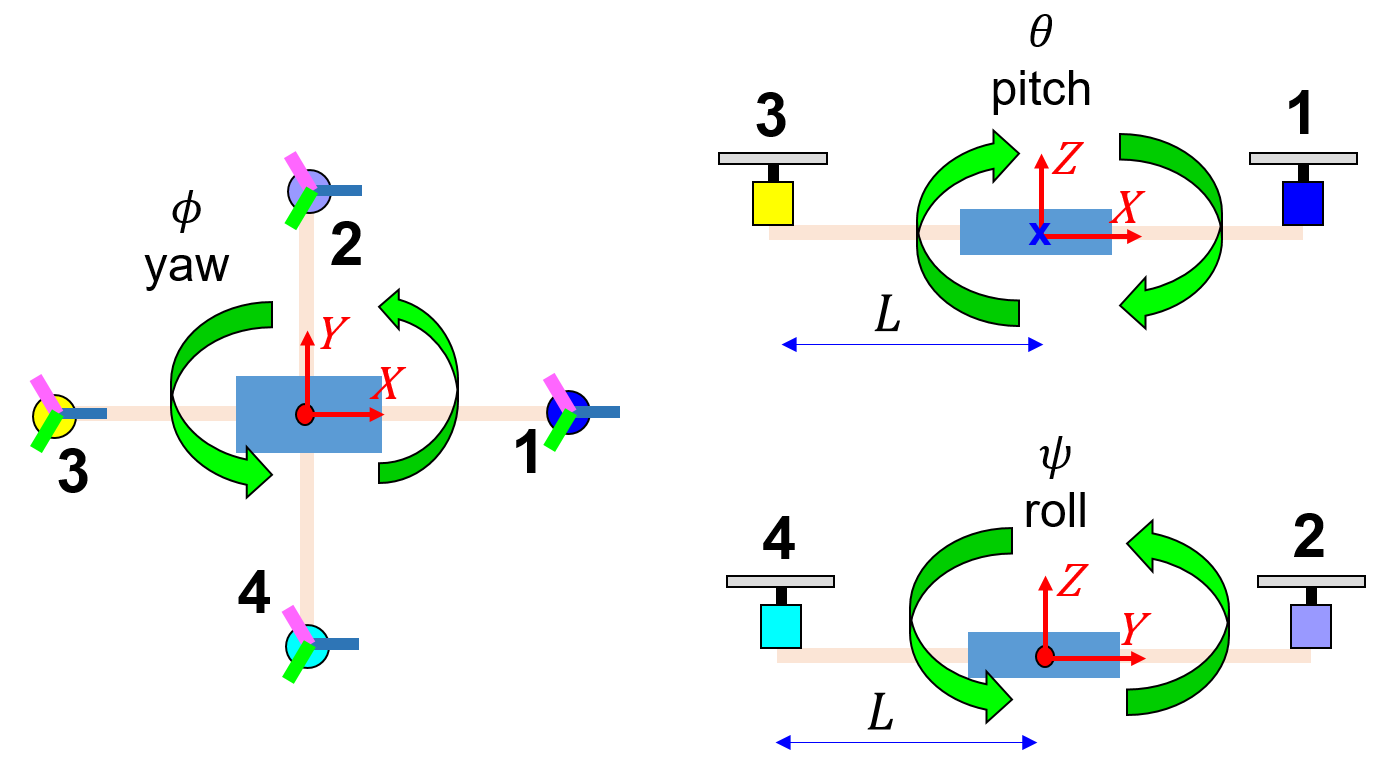

**Motivation:**

A common approach for integrating the equations of motion (Newton's) of a quadcopter, is to convert the vehicles angular velocity vector $^B_G\omega_B$ into it's corresponding Euler rates.  These Euler rates then get integrated to produce the angular orientation of the vehicle.  A problem arises however in that the conversion of $^B_G\omega_B$ to Euler rates contains a singularity at specific poses (eg: a ZYX Euler sequence has such a singularity at a pitch angle of 90 degrees).  An alternate approach then to propagating the vehicle's angular pose, is to integrate the DCM matrix directly.  This approach does NOT suffer from the singularity problem associatd with integrating Euler rates.

`Bradley Horton : 08-Aug-2016, bradley.horton@mathworks.com.au`

**The Background:**

Say we have an inertial frame referred to as the G-frame.  And we also have a body fixed frame referred to as the B-frame.  The B-frame is rotating relative to the G-frame.  The origins of the G-frame and B-frame are always co-incident.

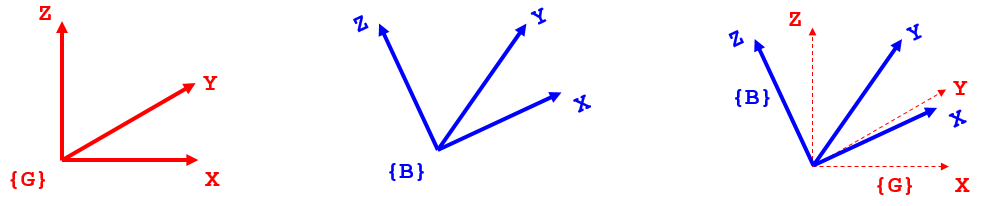

We can convert vectors expressed in each frame, into their corresponding components in the other frame, using Direction Cosine Matrices, eg:

- 
$$\matrix{
 ^Bv = {^BR_G} \thinspace . \thinspace ^Gv
}$$
 

- 
$$\matrix{
 ^Gv = {^GR_B} \thinspace . \thinspace ^Bv
}$$


In this tutorial we're going to derive the expression for:

-  
$${\dot{ {^GR_B} }}(t)$$


**Some Nomenclature:**

Define some nomenclature for the body B-frame:

- $\matrix{

 {^Bp}  
}$   :    the position of point *p*,  expressed in components of the B-frame.

- $\matrix{

 {^B_Gv_p}  
}$   :    the ***velocity*** of point *p*,  relative to the G-frame and expressed in components of the B-frame.

- $\matrix{

 {^Bv}  
}$    :     short hand notation for ${^B_Gv_p}$

- $\matrix{

 {^B_G\omega_B}  
}$   :    the ***angular velocity*** of the B-frame  relative to the G-frame and expressed in components of the B-frame.

- $\matrix{

 {^B\omega}  
}$    :     short hand notation for ${^B_G\omega_B}  $

Define some nomenclature for the inertial  G-frame:

- $\matrix{

 {^Gp}  
}$   :    the position of point *p*,  expressed in components of the G-frame.

- $\matrix{

 {^G_Gv_p}  
}$   :    the ***velocity*** of point *p*,  relative to the G-frame and expressed in components of the G-frame.

- $\matrix{

 {^Gv}  
}$    :     short hand notation for ${^G_Gv_p}$

- $\matrix{

 {^G_G\omega_B}  
}$   :    the ***angular velocity*** of the B-frame  relative to the G-frame and expressed in components of the G-frame.

- $\matrix{

 {^G\omega}  
}$    :     short hand notation for ${^G_G\omega_B}  $

Define some nomenclature for converting vectors between the B and G-frames and vice versa:

- 
$$\matrix{
 ^Bv = {^BR_G} \thinspace . \thinspace ^Gv
}$$
 

- 
$$\matrix{
 ^Gv = {^GR_B} \thinspace . \thinspace ^Bv
}$$


- 
$$\matrix{
 {^GR_B}  = {^BR_G \thinspace ^{-1}} = {^BR_G^T}
}$$


## The point p:

Consider a rigid body such as the humble potato.  We attach a body fixed frame to this body and call it the B-frame.  The B-frame rotates with the body - it is fixed to the body.  Consider also a fixed point on the potato, and let's call that point, ***p***.  Relative to the B-frame, the point ***p*** does NOT move, eg: imagine that point `p` is a "thumb tac"  that has been pushed into the potato.

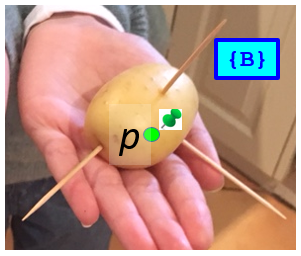

## Let's find ${\dot{ {^GR_B} }}(t)$:

Let's say that at time $t=0$, the B and G frames are co-incident.  Now since point *p* is "fixed" in the B-frame (ie: point *p* canNOT move relative to the B-frame), then we can write that:

 
$$\matrix{

 {^Gp(0)} = {^Bp(t) }  =  {^BR_G} \enspace .  {^Gp}(t) =   {^GR_B^T} \enspace .  {^Gp}(t)
}$$


The above result will prove useful in a moment when we decide to take the derivative of ${^Gp(t)}$.  Now let's use the above result to write an expression for ${^Gp(t)}$ :


$${^Gp(t)} = {^GR_B(t)} \enspace . \thinspace {^Bp(t)}$$



$${^Gp(t)} = {^GR_B(t)} \enspace . \thinspace {^Gp(0)} $$


Note how all of the p-terms in the above expression are expressed in components of the G-frame. So let's take the time derivative of ${^Gp(t)} $, where the derivative is taken with respect to the G-frame.

 
$$\matrix{

 {^G_Gv_p}  & = & 

_G \thinspace {\frac{d}{dt}}  
\pmatrix{ {^Gp(t)}  }

}$$
 
$$= \enspace
_G \thinspace {\frac{d}{dt}}  
\pmatrix{ {^GR_B(t)} \enspace . \thinspace {^Gp(0)}   }
$$
 
$$= \enspace
_G \thinspace {\frac{d}{dt}}  
\pmatrix{ {^GR_B(t)} } . \thinspace {^Gp(0)}  
$$

$$= \enspace
{\dot{ {^GR_B} }} \enspace . \thinspace {^Gp(0)}  
$$


which we can now write as: 


$$\matrix{

 {^G_Gv_p}  & = & {\dot{ {^GR_B} }} \enspace . \thinspace {^Gp(0)}  \cr

{^G_Gv_p}  & = &
 {\dot{ {^GR_B} }} \enspace . \thinspace {^GR_B^T} \enspace .  {^Gp}(t)

}$$
  

Let's define:


$$\matrix{

 {S(^G_G\omega_B)}  & = &
 {\dot{ {^GR_B} }} \enspace . \thinspace {^GR_B^T} 
}   $$
     
$$where$$
   
$$^G_G\omega_B = \pmatrix{
^G_G\omega_{Bx} \cr 
^G_G\omega_{By} \cr 
^G_G\omega_{Bz} \cr
} = 
 \pmatrix{
^G\omega_{x} \cr 
^G\omega_{y} \cr 
^G\omega_{z} \cr
} 
$$


Note that the above equation, can be restated as:   $\bf \matrix{

 {\dot{ {^GR_B} }}(t) & = &  {[S(^G_G\omega_B(t))]}  \enspace . \thinspace {^GR_B} (t)
}   $, which is a BIG result !!

Let's continue exploring our $^G_Gv_p$ expression:


$$\matrix{

 {^G_Gv_p}  & = &
 {S(^G_G\omega_B)}  \enspace .  {^Gp}(t)
}$$


Note that $ {S(^G_G\omega_B)}$ is actually a SKEW symmetric matrix, ie:  $ {S(^G_G\omega_B)}^T = -1 *{S(^G_G\omega_B)}$ - this is proven in **Appendix A**. And we can use this fact to rewrite the matrix equation into a vector CROSS product.  To do this, we'll make the following definition:


$$ {S(^G_G\omega_B)}   = 
\pmatrix{
0 &, & -{^G\omega_{z} & , & {^G\omega_{y}} \cr
{^G\omega_{z} &, & 0 & , & -{^G\omega_{x}} \cr
-{^G\omega_{y} &, & {^G\omega_{x} & , &0} 


}$$


And with this definition of $ {S(^G_G\omega_B)}$ we can now write:


$$\matrix{

 {^G_Gv_p}  & = &
 {^G_G\omega_B}  \enspace \times  {^Gp}(t)
}$$
     
$$where$$
    
$$"\times" \enspace  \text{denotes the vector cross product}$$


Let's confirm this last step with MATLAB:

syms omega_x omega_y omega_z
syms a b c

S = [          0,   -1*omega_z,       omega_y;
         omega_z,            0,    -1*omega_x;
      -1*omega_y,      omega_x,             0 ]

$$S = \left(\begin{array}{ccc} 0 & -\omega_{z} & \omega_{y}\\ \omega_{z} & 0 & -\omega_{x}\\ -\omega_{y} & \omega_{x} & 0 \end{array}\right)$$

  
p     = [a,b,c].';

omega = [omega_x omega_y omega_z].';

So here's the result of doing    $\matrix{

 {^G_Gv_p}  & = &
 {S(^G_G\omega_B)}  \enspace .  {^Gp}(t)
}$

mat_mult_result  = S * p

$$mat\_mult\_result = \left(\begin{array}{c} c\,\omega_{y}-b\,\omega_{z}\\ a\,\omega_{z}-c\,\omega_{x}\\ b\,\omega_{x}-a\,\omega_{y} \end{array}\right)$$

And here's the result of doing    $\matrix{

 {^G_Gv_p}  & = &
 {^G_G\omega_B}  \enspace \times  {^Gp}(t)
}$

vec_cross_result = cross(omega, p)

$$vec\_cross\_result = \left(\begin{array}{c} c\,\omega_{y}-b\,\omega_{z}\\ a\,\omega_{z}-c\,\omega_{x}\\ b\,\omega_{x}-a\,\omega_{y} \end{array}\right)$$

## The BIG result:

One of the BIG results that we derived in the previous section was this one:


$$\matrix{

 {S(^G_G\omega_B)}  & = &
 {\dot{ {^GR_B} }} \enspace . \thinspace {^GR_B^T} 
}   $$
     
$$where$$
   
$$^G_G\omega_B = \pmatrix{
^G_G\omega_{Bx} \cr 
^G_G\omega_{By} \cr 
^G_G\omega_{Bz} \cr
} = 
 \pmatrix{
^G\omega_{x} \cr 
^G\omega_{y} \cr 
^G\omega_{z} \cr
} 
$$


Or, after some simple rearrangement:


$$\matrix{

 {\dot{ {^GR_B} }}(t) & = &  {[S(^G_G\omega_B(t))]}  \enspace . \thinspace {^GR_B} (t)
}   $$


This equation tells us how to compute the derivative of the Direction Cosine Matrix $^GR_B$ if we know the angular velocity of the B-frame relative to the G-frame and expressed in components of the G-frame, ie:  $^G_G\omega_B$.

## The implementation of the BIG result: - part 1

The significance of this expression for ${\dot{ {^GR_B} }}$, is that we can use it as a mechanism to propagate the orientation of a rigid body.  Using this approach there are NO singularities that would prevent us from computing ${^GR_B}(t) }$.  The implementation of this algorithm would look something like this:

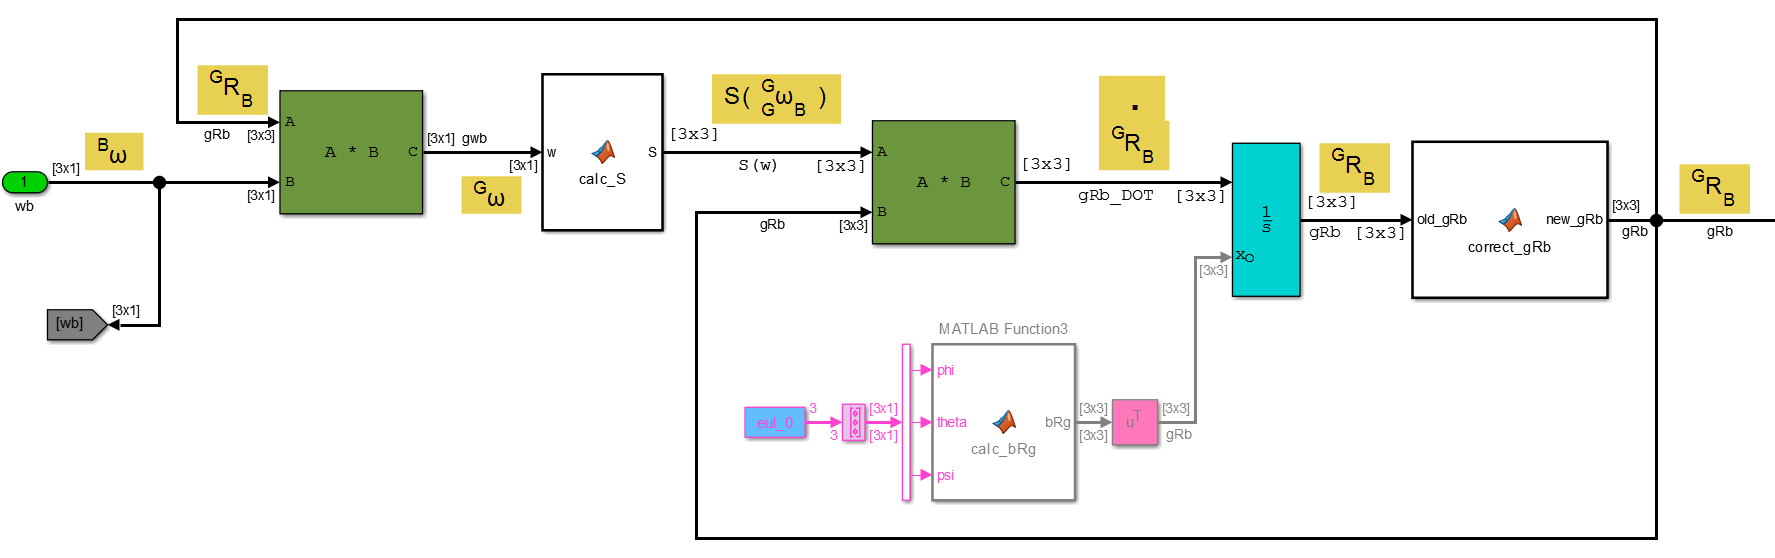

Note that to compute ${^GR_B}(t=0) }$, we could let the user specify an initial Euler angle configuration.  Also, the `calc_S` function would be:

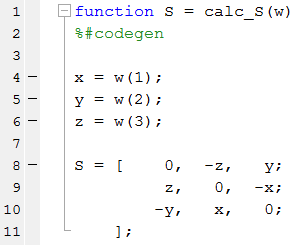

When we integrate ${\dot{ {^GR_B} }}$, we would expect that the orthogonality relationship of $\matrix{
  {^GR_B(t)} } \enspace . \thinspace {^GR_B(t)^T}= I 
}   $ would still  be true.  And it almost is !  The combination of "numerically" intergrating a derivative and the finite word size of computer calculations, means that we end up with a relationship that is more like this:

   
$$\matrix{
  {^GR_B(t)} } \enspace . \thinspace {^GR_B(t)^T}= I + \delta e \enspace \text{,where } \quad  \delta e \quad \text{ is a matrix of small terms}}
}   $$


We can reduce this $\delta e$ term using a correction technique such as the one proposed by William Premerlani and Paul Bizard (see: [**HERE**](https://www.google.com.au/url?sa=t&rct=j&q=&esrc=s&source=web&cd=1&cad=rja&uact=8&ved=0ahUKEwjRv57ztLXOAhUJlZQKHS_qA2MQFggdMAA&url=https%3A%2F%2Fgentlenav.googlecode.com%2Ffiles%2FDCMDraft2.pdf&usg=AFQjCNFd94N3cdq67qbwEvZZ-S2Rn5hhzw)).

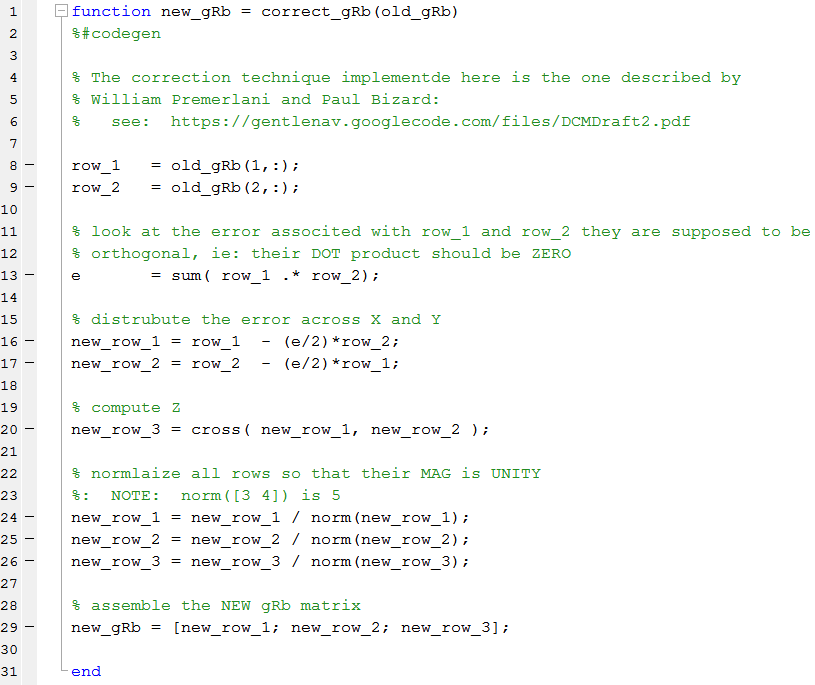

## The implementation of the BIG result: - part 2

If you'd like to see how we actually use the relationship:


$$\matrix{

 {\dot{ {^GR_B} }}(t) & = &  {[S(^G_G\omega_B(t))]}  \enspace . \thinspace {^GR_B} (t)
}   $$


then have a look at the Simulink model called `<``bh_6dof_DCM_integrate.slx``>. ` In this model we integrate ${\dot{ {^GR_B} }}$ to determine the angular orientation of the quadcopter.

clear; clc; bh_quad_params
open_system('bh_6dof_DCM_integrate')

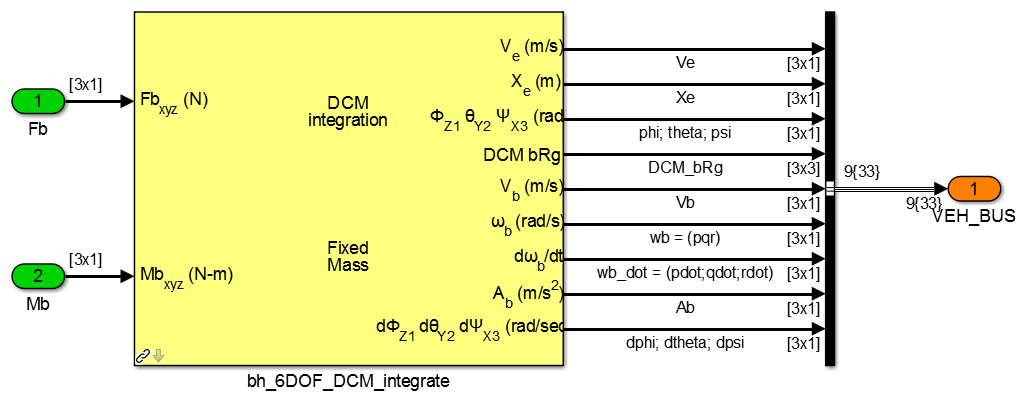

# Appendix A:  The **skew symmetry** of ${\dot{ {^GR_B} }} \enspace . \thinspace {^GR_B^T} $

Earlier in this tutorial we defined the following:


$$\matrix{

 {S(^G_G\omega_B)}  & = &
 {\dot{ {^GR_B} }} \enspace . \thinspace {^GR_B^T} 
}   $$
     
$$where$$
   
$$^G_G\omega_B = \pmatrix{
^G_G\omega_{Bx} \cr 
^G_G\omega_{By} \cr 
^G_G\omega_{Bz} \cr
} = 
 \pmatrix{
^G\omega_{x} \cr 
^G\omega_{y} \cr 
^G\omega_{z} \cr
} 
$$


and we made the statement that $ {S(^G_G\omega_B)} $ was a  SKEW symmetric matrix, ie:  $ {S(^G_G\omega_B)}^T = -1 *{S(^G_G\omega_B)}$.  So let's prove that now.  What we want to show is that:


$$\matrix{

\bullet  &
(\dot{ {^GR_B} } \enspace . \thinspace {^GR_B^T})^T & = & -1*( \dot{ {^GR_B} } \enspace . \thinspace {^GR_B^T} )
}   $$


We start with the identity:


$$\matrix{
  {^GR_B(t)} } \enspace . \thinspace {^GR_B(t)^T}= I 
}   $$


and then take the derivative w.r.t $t$ on both sides:


$$\dot{ {^GR_B} } \thinspace . \thinspace {^GR_B^T}  \enspace + \enspace 
 {^GR_B} \thinspace . \thinspace \dot{ {^GR_B^T} }  \enspace = \enspace 0$$


which then gives us:


$${^GR_B} \thinspace . \thinspace \dot{ {^GR_B^T} }  = -1*\dot{ {^GR_B} } \thinspace . \thinspace {^GR_B^T} $$


And we note that the LHS could be written as:    $ {^GR_B}  \thinspace . \thinspace \dot{^GR_B^T} \equiv 
(\thinspace \dot{^GR_B}  \thinspace . \thinspace  {^GR_B^T}  \thinspace)^T$ using the standard matrix algebra relationship that $(A \thinspace . \thinspace B)^T = B^T \thinspace . \thinspace A^T$.  So we can finally write:


$$\matrix{

\bullet  &
(\dot{ {^GR_B} } \enspace . \thinspace {^GR_B^T})^T & = & -1* ( \dot{ {^GR_B} } \enspace . \thinspace {^GR_B^T} )
}   $$


Which is our proof that $\matrix{

 {S(^G_G\omega_B)} 
}   $ is SKEW symmetric.